## Matlab Examples

This file contains a running example of using matlab to solve the problems done in class on the board or in the slides.

### Laplace Transform

You can use the Matlab Symbolic tool box to do Laplace transforms:

clear
syms s t
f(t)=t*sin(3*t)

$$f(t) = t\,\sin\left(3\,t\right)$$

F(s)=laplace(f(t))

$$F(s) = \frac{6\,s}{{\left(s^{2}+9\right)}^{2}}$$

You can do the inverse Laplace transform as well

ilaplace(F(s))

$$ans = t\,\sin\left(3\,t\right)$$

#### Partial Fractions Expansion

You can do partial fraction expansions to check your hand calculations too! Consider the Laplace transform from the 2nd set of slides *Modeling in the Frequence Domain*, slide 18

F(s)=(s^2+2*s-3)/((s - 1)*(s + 1)^2*(s^2 + 1))

$$F(s) = \frac{s^{2}+2\,s-3}{\left(s^{2}+1\right)\,\left(s-1\right)\,{\left(s+1\right)}^{2}}$$

partfrac(F(s))

$$ans = \frac{3}{2\,\left(s+1\right)}-\frac{\frac{3\,s}{2}-\frac{1}{2}}{s^{2}+1}+\frac{1}{{\left(s+1\right)}^{2}}$$

In this case we would expect


$$ F(s) = \frac{s^2 +2s - 3}{(s-1)(s+1)^2(s^2 + 1)} \\
  =  \frac{A}{s-1} + \frac{B}{s+1} + \frac{C}{(s+1)^2} + \frac{Ds + E}{s^2 + 1} $$


but there is no $\frac{A}{s-1}$ term! Why not?

In this case $A=0$ since there is pole zero cancellation since 


$$F(s) = \frac{s^2 +2s - 3}{(s-1)(s+1)^2(s^2 + 1)} \\
=   \frac{(s-1)(s+3)}{(s-1)(s+1)^2(s^2 + 1)} \\$$


so the zero at $s=1$ cancels with the pole at $s=1$.

F(s)

$$ans = \frac{s^{2}+2\,s-3}{\left(s^{2}+1\right)\,\left(s-1\right)\,{\left(s+1\right)}^{2}}$$

ilaplace(F(s))

$$ans = \frac{3\,{\mathrm{e}}^{-t}}{2}-\frac{3\,\cos\left(t\right)}{2}+\frac{\sin\left(t\right)}{2}+t\,{\mathrm{e}}^{-t}$$

Let's try another example

Y=1/(s*(s+2)^2*(s+1))

$$Y = \frac{1}{s\,\left(s+1\right)\,{\left(s+2\right)}^{2}}$$

partfrac(Y)

$$ans = \frac{3}{4\,\left(s+2\right)}-\frac{1}{s+1}+\frac{1}{2\,{\left(s+2\right)}^{2}}+\frac{1}{4\,s}$$

ilaplace(Y)

$$ans = \frac{3\,{\mathrm{e}}^{-2\,t}}{4}-{\mathrm{e}}^{-t}+\frac{t\,{\mathrm{e}}^{-2\,t}}{2}+\frac{1}{4}$$

Doing the inverse Laplace of the example from slide 21 we have:

G(s)=3/(s*(s^2 + 2*s + 5))

$$G(s) = \frac{3}{s\,\left(s^{2}+2\,s+5\right)}$$

ilaplace(G(s))

$$ans = \frac{3}{5}-\frac{3\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)+\frac{\sin\left(2\,t\right)}{2}\right)}{5}$$

If we want to check our work by hand we could do the partial fractions expansion:

partfrac(G(s))

$$ans = \frac{3}{5\,s}-\frac{\frac{3\,s}{5}+\frac{6}{5}}{s^{2}+2\,s+5}$$

### Deriving Transfer Function

We now should how you can use the Matlab symbolic toolbox to write down and solve equations for transfer functions.

Consider then example circuit from Nise Fig. 2.6:

  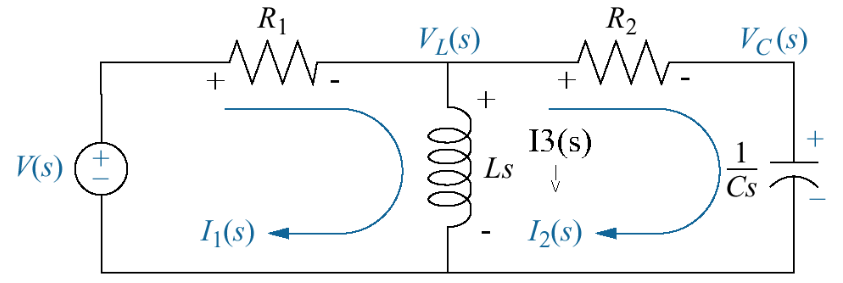

Let's check our answers that we got by hand for the mesh currents:

clear
syms s I1 I2 R1 R2 C L V 

Loop1 equation:

V-R1*I1-L*s*(I1-I2)==0

$$ans = V-I_{1}\,R_{1}-L\,s\,\left(I_{1}-I_{2}\right)=0$$

-1*ans

$$ans = I_{1}\,R_{1}-V+L\,s\,\left(I_{1}-I_{2}\right)=0$$

ans+V

$$ans = I_{1}\,R_{1}+L\,s\,\left(I_{1}-I_{2}\right)=V$$

eq1=collect(collect(ans,I2),I1)

$$eq1 = \left(R_{1}+L\,s\right)\,I_{1}+\left(-L\,s\right)\,I_{2}=V$$

Loop 2 Equation:

 -R2*I2-1/(C*s)*I2 - L*s*(I2-I1)==0

$$ans = L\,s\,\left(I_{1}-I_{2}\right)-\frac{I_{2}}{C\,s}-I_{2}\,R_{2}=0$$

-1*ans

$$ans = I_{2}\,R_{2}+\frac{I_{2}}{C\,s}-L\,s\,\left(I_{1}-I_{2}\right)=0$$

eq2=collect(collect(ans,I2),I1)

$$eq2 = \left(-L\,s\right)\,I_{1}+\left(R_{2}+L\,s+\frac{1}{C\,s}\right)\,I_{2}=0$$

Below we will solve this the "long way" verifying our hand calculations step by step, and the "short way" just directly using the $\texttt{solve()}$ command.

**Long way:**

[A,b]=equationsToMatrix([eq1,eq2],[I1,I2])

$$A = \left(\begin{array}{cc} R_{1}+L\,s & -L\,s\\ -L\,s & R_{2}+L\,s+\frac{1}{C\,s} \end{array}\right)$$

$$b = \left(\begin{array}{c} V\\ 0 \end{array}\right)$$

Then $I_2(s)=\frac{\det \mathbf{A}_2}{\det \mathbf{A}}$ where $A_2$ is the matrix obtained by replacing the 2nd column of $\mathbf{A}$ by $\mathbf{b}$. In matlab we can construc $\mathbf{A}_2$ as follows:

A2=[A(:,1) b]

$$A2 = \left(\begin{array}{cc} R_{1}+L\,s & V\\ -L\,s & 0 \end{array}\right)$$

det(A2)

$$ans = L\,V\,s$$

det(A)

$$ans = \frac{R_{1}+L\,s+C\,L\,R_{1}\,s^{2}+C\,L\,R_{2}\,s^{2}+C\,R_{1}\,R_{2}\,s}{C\,s}$$

collect(ans)

$$ans = \frac{\left(C\,L\,R_{1}+C\,L\,R_{2}\right)\,s^{2}+\left(L+C\,R_{1}\,R_{2}\right)\,s+R_{1}}{C\,s}$$

so we can now solve for $I_2(s)$ as

I_2=det(A2)/det(A)

$$I\_2 = \frac{C\,L\,V\,s^{2}}{R_{1}+L\,s+C\,L\,R_{1}\,s^{2}+C\,L\,R_{2}\,s^{2}+C\,R_{1}\,R_{2}\,s}$$

I_2=collect(I_2)

$$I\_2 = \frac{\left(C\,L\,V\right)\,s^{2}}{\left(C\,L\,R_{1}+C\,L\,R_{2}\right)\,s^{2}+\left(L+C\,R_{1}\,R_{2}\right)\,s+R_{1}}$$

G_I_2=collect(I2/V)

$$G\_I\_2 = \frac{I_{2}}{V}$$

**Short way:**


LoopSoln = solve([eq1,eq2],[I1 I2])

LoopSoln = struct with fields:
    I1: (V*(C*L*s^2 + C*R2*s + 1))/(R1 + L*s + C*L*R1*s^2 + C*L*R2*s^2 + C*R1*R2*s)
    I2: (C*L*V*s^2)/(R1 + L*s + C*L*R1*s^2 + C*L*R2*s^2 + C*R1*R2*s)


LoopSoln.I2/V

$$ans = \frac{C\,L\,s^{2}}{R_{1}+L\,s+C\,L\,R_{1}\,s^{2}+C\,L\,R_{2}\,s^{2}+C\,R_{1}\,R_{2}\,s}$$

G_VtoI2 =collect(ans)

$$G\_VtoI2 = \frac{\left(C\,L\right)\,s^{2}}{\left(C\,L\,R_{1}+C\,L\,R_{2}\right)\,s^{2}+\left(L+C\,R_{1}\,R_{2}\right)\,s+R_{1}}$$

We know that the voltage across the capcitor is $V_c=\frac{1}{Cs}I_2$ so

V_c=(1/(C*s))*LoopSoln.I2

$$V\_c = \frac{L\,V\,s}{R_{1}+L\,s+C\,L\,R_{1}\,s^{2}+C\,L\,R_{2}\,s^{2}+C\,R_{1}\,R_{2}\,s}$$

So $G_{V_c}(s)=\frac{V_c(s)}{V(s)}$

G_Vc=collect(V_c/V)

$$G\_Vc = \frac{L\,s}{\left(C\,L\,R_{1}+C\,L\,R_{2}\right)\,s^{2}+\left(L+C\,R_{1}\,R_{2}\right)\,s+R_{1}}$$

Again consider then example circuit from Nise Fig. 2.6:

  

In class we solver this circuit using Mesh Analysis to get the tranfer function $\frac{I_2(s)}{V(s)}$ and then $\frac{V_c(s)}{V(s)}$. 

Now we will use Nodal analysis and Matlab to solve for the transfer function $\frac{V_C(s)}{V(s)}$.

If we know the voltage $V_L(s)$, then we can solve for any other quantity of interest easily. In our case we are interested in $V_C(s)$.

If we have already solved for $V_L(s)$ then the current 

$I_2(s)=\frac{V_L(s)}{R_2+\frac{1}{Cs}}$  and then $V_C(s)=I_2(s) \frac{1}{Cs}$

We will now use Kirkoff's Current Law to write down the equation for the currents leaving node in the middle of the top of the curcuit where $V_L(s)$ is written.


$$\frac{V_L-V}{R_1}+\frac{V_L}{Ls}+\frac{V_L}{{R_2+\frac{1}{Cs}}}=0$$


Solve for $V_L$:


$$\left (\frac{1}{R_1}+\frac{1}{Ls}+\frac{1}{R_2+\frac{1}{Cs}}\right )V_L=\frac{V}{R_1}\\
\left(\frac{Ls\left(R_2+\frac{1}{Cs}\right)+R_1\left(R_2+\frac{1}{Cs}\right)+R_1Ls}{R_1Ls\left(R_2+\frac{1}{Cs}\right)}\right)V_L=\frac{V}{R_1}
$$


Multiply LHS by $\frac{Cs}{Cs}$ to get


$$\left(\frac{Ls\left(R_2Cs+1\right)+R_1\left(R_2Cs+1\right)+R_1LCs^2}{R_1Ls\left(R_2Cs+1\right)}\right)V_L=\frac{V}{R_1}
$$


Collect powers of $s$:


$$\left(\frac{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}{R_1Ls\left(R_2Cs+1\right)}\right)V_L=\frac{V}{R_1}
$$


Solving for $V_L$ we get:


$$V_L=\left(\frac{R_1Ls\left(R_2Cs+1\right)}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}\right)\frac{V}{R_1}
$$


Canceling $R_1$ on the RHS we get:


$$V_L=\left(\frac{Ls\left(R_2Cs+1\right)}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}\right)V$$


Now we can use the voltage divider law to get:


$$V_C=V_L\left(\frac{\frac{1}{Cs}}{R_2+\frac{1}{Cs}}\right )\\
=\frac{V_L}{R_2Cs+1}\\
=\left(\frac{Ls\left(R_2Cs+1\right)}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}\right)V\left(\frac{1}{R_2Cs+1}\right )$$


Canceling $(R_2Cs+1)$ we get:


$$V_c=\left(\frac{Ls}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}\right)V$$


So we get the transfer function:


$$G(s)=\frac{V_c(s)}{V(s)}=\frac{Ls}{\left(R_1+R_2\right)LCs^2+\left(L+R_1R_2C\right)s+R_1}$$


How would we use Matlab to do the above algebraic manipulations?

clear
syms s I_2 R_1 R_2 C L V V_L V_C
V_L = solve((V_L-V)/R_1+V_L/(L*s)+V_L/(R_2+1/(C*s)) == 0,V_L)

$$V\_L = \frac{V}{R_{1}\,\left(\frac{1}{R_{1}}+\frac{1}{L\,s}+\frac{1}{R_{2}+\frac{1}{C\,s}}\right)}$$

%V_L(s)=simplifyFraction(V_L(s),'Expand',true)
V_L=collect(V_L)

$$V\_L = \frac{\left(C\,L\,R_{2}\,V\right)\,s^{2}+\left(L\,V\right)\,s}{\left(C\,L\,R_{1}+C\,L\,R_{2}\right)\,s^{2}+\left(L+C\,R_{1}\,R_{2}\right)\,s+R_{1}}$$

V_C(s)=V_L*((1/(C*s))/(R_2+1/(C*s)))

$$V\_C(s) = \frac{\left(C\,L\,R_{2}\,V\right)\,s^{2}+\left(L\,V\right)\,s}{C\,s\,\left(R_{2}+\frac{1}{C\,s}\right)\,\left(\left(C\,L\,R_{1}+C\,L\,R_{2}\right)\,s^{2}+\left(L+C\,R_{1}\,R_{2}\right)\,s+R_{1}\right)}$$

G(s)=collect(V_C(s)/V)

$$G(s) = \frac{L\,s}{\left(C\,L\,R_{1}+C\,L\,R_{2}\right)\,s^{2}+\left(L+C\,R_{1}\,R_{2}\right)\,s+R_{1}}$$

OK. So this is definitely faster than doing it by hand once you know the Matlab commands!

**2. System Modeling: Electric Circuits (20 marks)**

a) (5 marks) Redraw the circuit with the components replaced by their Laplace domain impedances.

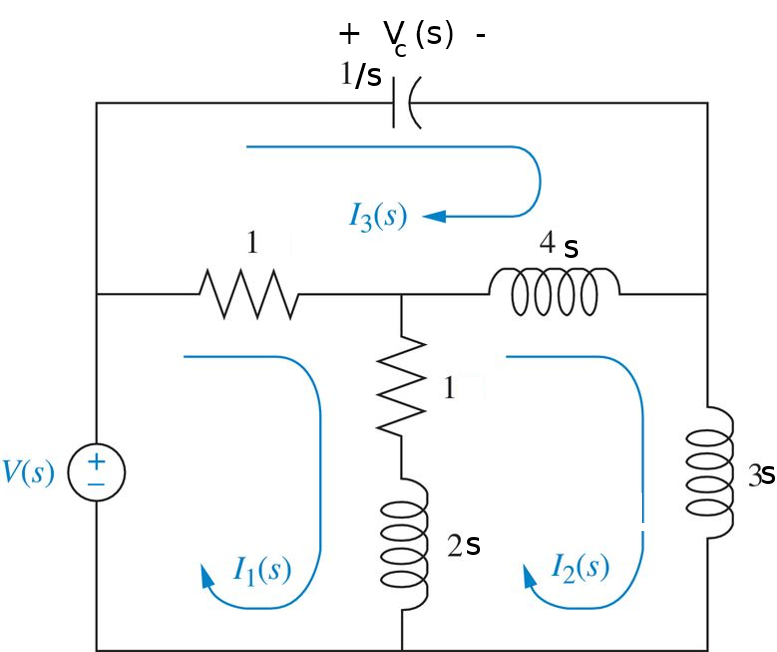

b) (5 marks) Write down the loop equation(s) that you would solve for the circuit including the equation for the output $V_C (s)$.

For Loop 1 (Bottom LHS of circuit)

clear
syms s I_1 I_2 I_3 V_c V
LoopEq1= 1*(I_1 - I_3) + (2*s + 1)*(I_1 - I_2) == V

$$LoopEq1 = I_{1}-I_{3}+\left(2\,s+1\right)\,\left(I_{1}-I_{2}\right)=V$$

LoopEq1=collect(collect(LoopEq1, I_2),I_1)

$$LoopEq1 = \left(2\,s+2\right)\,I_{1}-I_{3}+\left(-2\,s-1\right)\,I_{2}=V$$

For Loop 2(Bottom RHS of circuit)

LoopEq2=(2*s + 1)*(I_2 - I_1) + 4*s*(I_2 - I_3) + 3*s*I_2 == 0

$$LoopEq2 = 3\,I_{2}\,s+4\,s\,\left(I_{2}-I_{3}\right)-\left(2\,s+1\right)\,\left(I_{1}-I_{2}\right)=0$$

LoopEq2=collect(collect(LoopEq2, I_2),I_1)

$$LoopEq2 = \left(-2\,s-1\right)\,I_{1}-4\,I_{3}\,s+\left(9\,s+1\right)\,I_{2}=0$$

For Loop 3(Top of circuit)

LoopEq3=I_3+4*s*(I_3-I_2)+ 1*(I_3-I_2)==0

$$LoopEq3 = 2\,I_{3}-I_{2}-4\,s\,\left(I_{2}-I_{3}\right)=0$$

Output equation:

LoopOutput=V_c==I_3/s

$$LoopOutput = V_{c}=\frac{I_{3}}{s}$$

c) (5 marks) Write down the node equation(s) that you would use to solve for the transfer function from the input $V$ to the output $V_C$.

syms s V_A V_B V
NodeEqn1=(V_A-V)/1 + V_A/(2*s+1) + (V_A-V_B)/(4*s)==0

$$NodeEqn1 = V_{A}-V+\frac{V_{A}}{2\,s+1}+\frac{V_{A}-V_{B}}{4\,s}=0$$

NodeEqn1=collect(NodeEqn1,V_A)

$$NodeEqn1 = \left(\frac{1}{2\,s+1}+\frac{1}{4\,s}+1\right)\,V_{A}-V-\frac{V_{B}}{4\,s}=0$$

NodeEqn1=collect(NodeEqn1+V,V_A)

$$NodeEqn1 = \left(\frac{1}{2\,s+1}+\frac{1}{4\,s}+1\right)\,V_{A}-\frac{V_{B}}{4\,s}=V$$

NodeEqn2=(V_B-V)/(1/s)+(V_B-V_A)/(4*s)+V_B/(3*s)==0

$$NodeEqn2 = \frac{V_{B}}{3\,s}-s\,\left(V-V_{B}\right)-\frac{V_{A}-V_{B}}{4\,s}=0$$

NodeEqn2=collect(NodeEqn2,V)

$$NodeEqn2 = \left(-s\right)\,V+V_{B}\,s+\frac{V_{B}}{3\,s}-\frac{V_{A}-V_{B}}{4\,s}=0$$

NodeEqn2=collect(collect(NodeEqn2,V_B),V_A)

$$NodeEqn2 = \left(-\frac{1}{4\,s}\right)\,V_{A}+\left(s+\frac{7}{12\,s}\right)\,V_{B}+\left(-s\right)\,V=0$$

Output equation is:

V_c=V-V_B

$$V\_c = V-V_{B}$$

d) (5 marks) Find the transfer function $G(s)=\frac{V_C(s)}{V(s)}$.

eqns = [NodeEqn1, NodeEqn2];
vars = [V_A, V_B];
NodeSoln=solve(eqns,vars)

NodeSoln = struct with fields:
    V_A: (V*s*(2*s + 1)*(12*s^2 + 3*s + 7))/(24*s^4 + 30*s^3 + 17*s^2 + 16*s + 1)
    V_B: (3*V*s*(8*s^3 + 10*s^2 + 3*s + 1))/(24*s^4 + 30*s^3 + 17*s^2 + 16*s + 1)


NodeSoln.V_B

$$ans = \frac{3\,V\,s\,\left(8\,s^{3}+10\,s^{2}+3\,s+1\right)}{24\,s^{4}+30\,s^{3}+17\,s^{2}+16\,s+1}$$

G_n_V_C=collect((V-NodeSoln.V_B)/V)

$$G\_n\_V\_C = \frac{8\,s^{2}+13\,s+1}{24\,s^{4}+30\,s^{3}+17\,s^{2}+16\,s+1}$$

Now let's try a mechanical system.

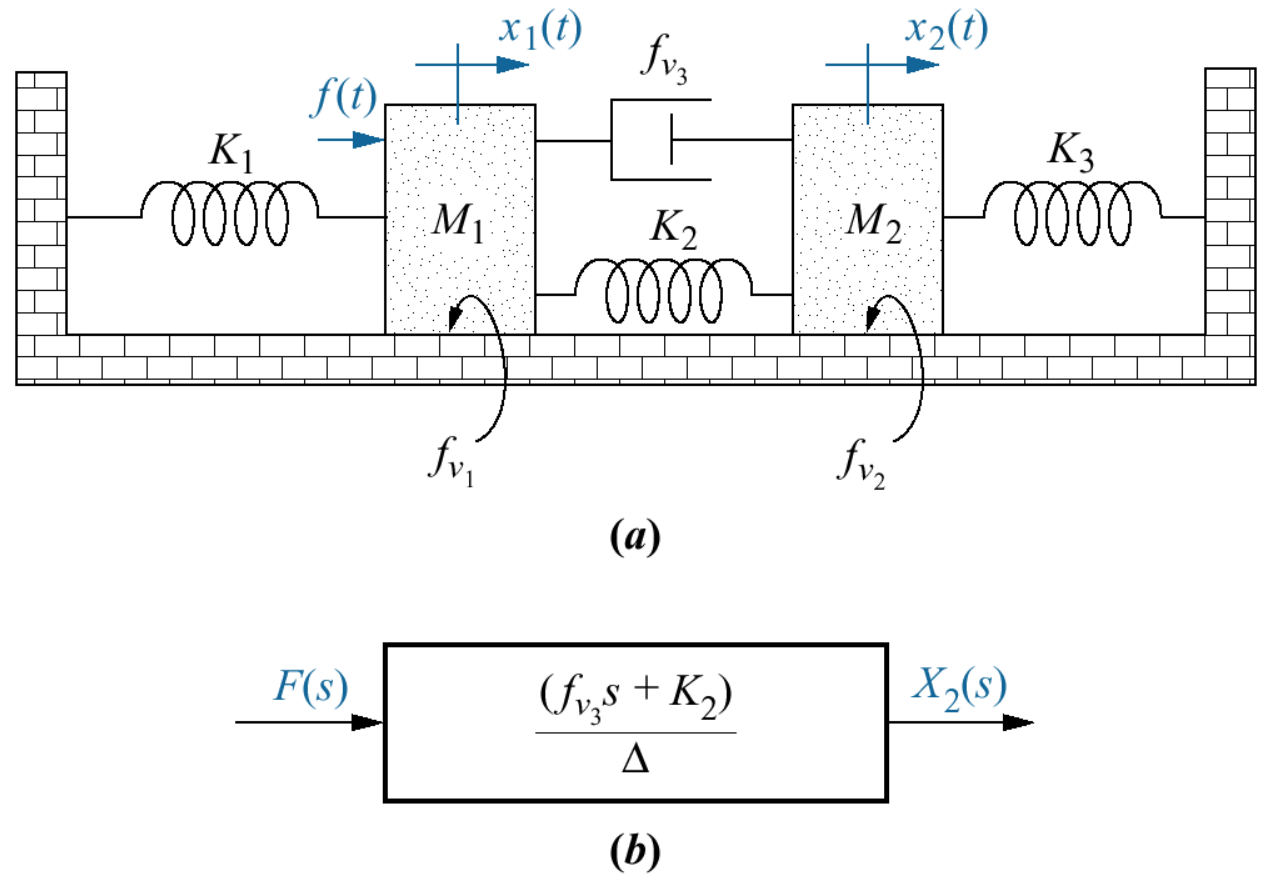

clear
syms s X_1 X_2 F(s) K_1 K_2 K_3 f_v_1 f_v_2 f_v_3 M_1 M_2

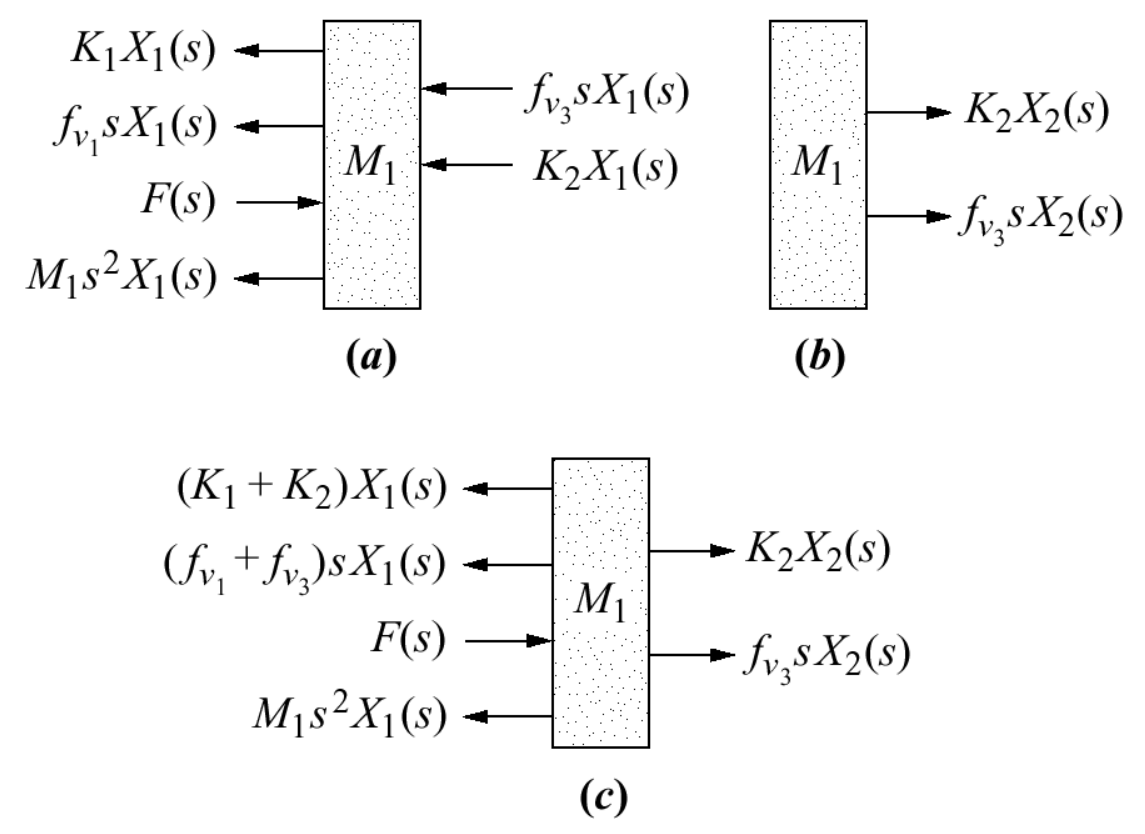

eq1 = K_1*X_1+K_2*X_1+f_v_1*s*X_1+f_v_3*s*X_1+M_1*s^2*X_1 == F(s)+K_2*X_2+f_v_3*s*X_2

Now consider $M_2$.

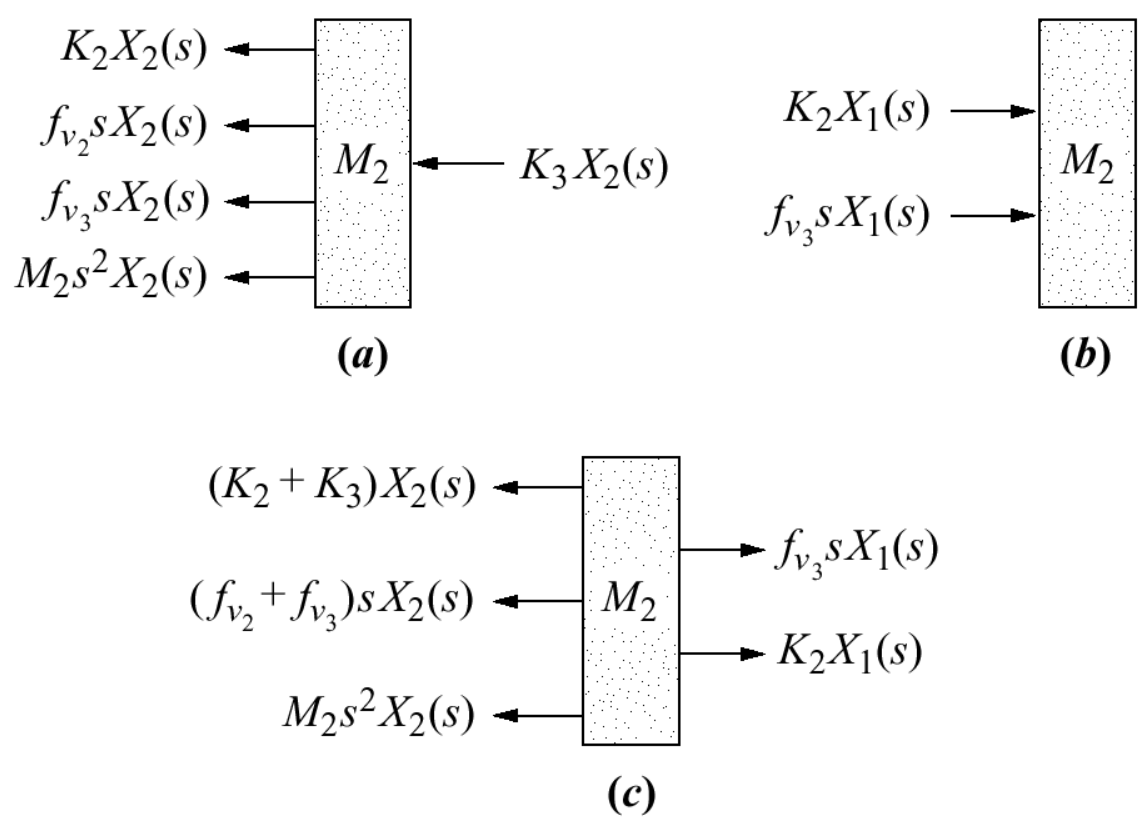

eq2 = (K_1+K_2)*X_2+(f_v_2+f_v_3)*s*X_2+M_2*s^2*X_2 == f_v_3*s*X_1+K_2*X_1
solns=solve([eq1,eq2],[X_1,X_2])
G_2=collect(solns.X_2/F(s))

Alternatively, rather than using the "solve" command I could have done Cramer's rule to solve for transfer function $G_2(s)=\frac{X_2(s)}{F(s)}$.

To do this let 


$$\mathbf{x}=\left [\begin{array}{c} X_1(s)\\X_2(s)\end{array}\right ]$$


Then eq1 and eq2 can be written in matrix for $\mathbf{Ax}=\mathbf{b}$. First let's clean up the equations to help put them in the right format:

eq1
eq1=isolate(eq1,F(s))
%eq1= eq1-(f)
eq1=rhs(eq1)==lhs(eq1)
eq1=collect(collect(eq1,X_2),X_1)
%eq1=eq1-(f_v_3*s+K_2)*X_2
eq1=collect(collect(eq1,X_2),X_1)
%eq1=isolate(eq1,F(s))
%eq1= eq1-(f)
%eq1=rhs(eq1)==lhs(eq1)
%eq1=collect(collect(eq1,X_2),X_1)
eq2=collect(collect(eq2,X_1),X_2)
A=[M_1*s^2 + f_v_1*s + f_v_3*s + K_1+K_2  -(f_v_3*s + K_2); -(f_v_3*s + K_2)  M_2*s^2+(f_v_2+f_v_3)*s+(K_1 + K_2)]

and


b=[F(s);0]

Alternatively rather than manually writing down the equations in matrix format we can use Matlab's $\texttt{equationsToMatrix}$ command to do this automatically and eliminate the possibility of making a manaul error in copying!

[A,b]=equationsToMatrix([eq1,eq2],[X_1,X_2])

Then $X_2(s)=\frac{\det \mathbf{A}_2}{\det \mathbf{A}}$ where $A_2$ is the matrix obtained by replacing the 2nd column of $\mathbf{A}$ by $\mathbf{b}$. In matlab we can construc $\mathbf{A}_2$ as follows:

A_2=[A(:,1) b]
det(A_2)
det(A)
collect(ans)

so we can now solve for $X_2(s)$ as

X_2=det(A_2)/det(A)

Then we get $G_2(s)=\frac{X_2(s)}{F(s)$ where we use the collect function to collect powers of $s$.

G_2alt=collect(X_2/F(s))

Check if it is the same answer as the other way we solved for it:

G_2-G_2alt

Looks like we did both calculations correctly.

#### Rotational Transfer Functions

Consider the example:

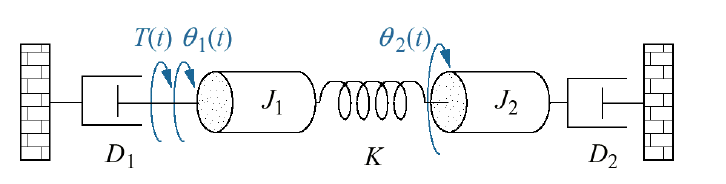

Consider $J_1$:

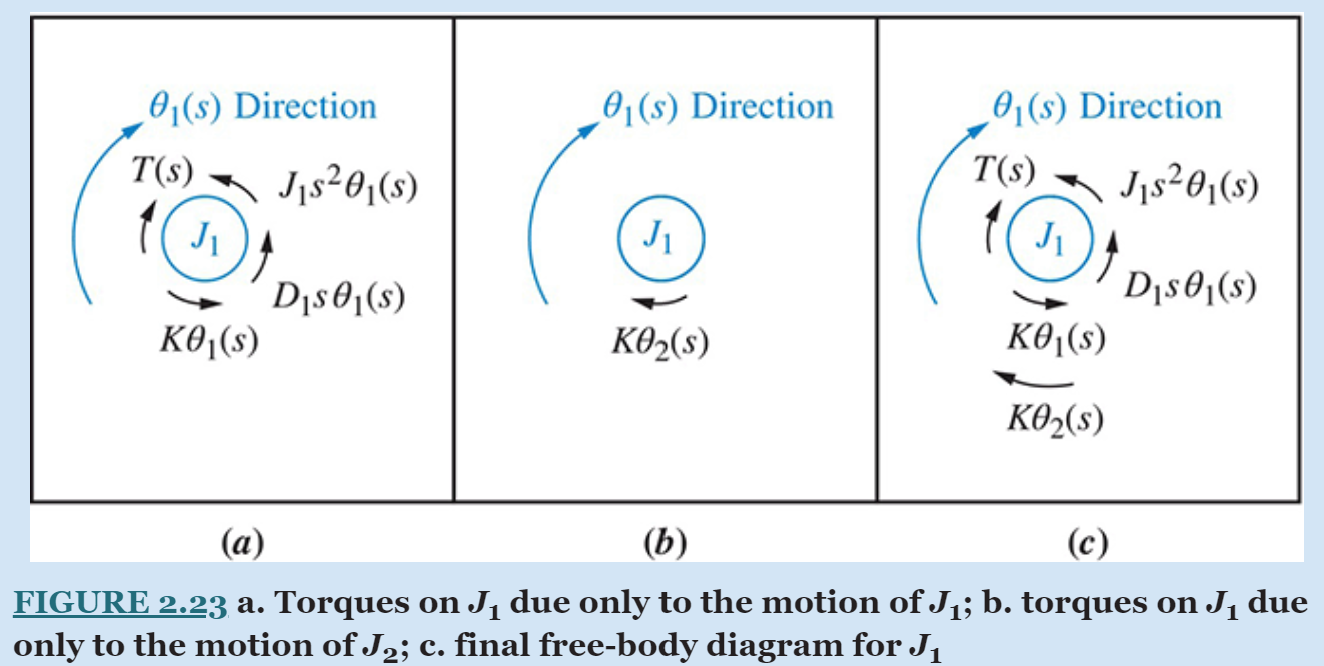

syms D_1 D_2 K J_1 J_2 T theta_1 theta_2 s
J_1*s^2*theta_1+D_1*s*theta_1+K*theta_1==T+K*theta_2
ans-K*theta_2
eq1 = collect(collect(ans,theta_2),theta_1)

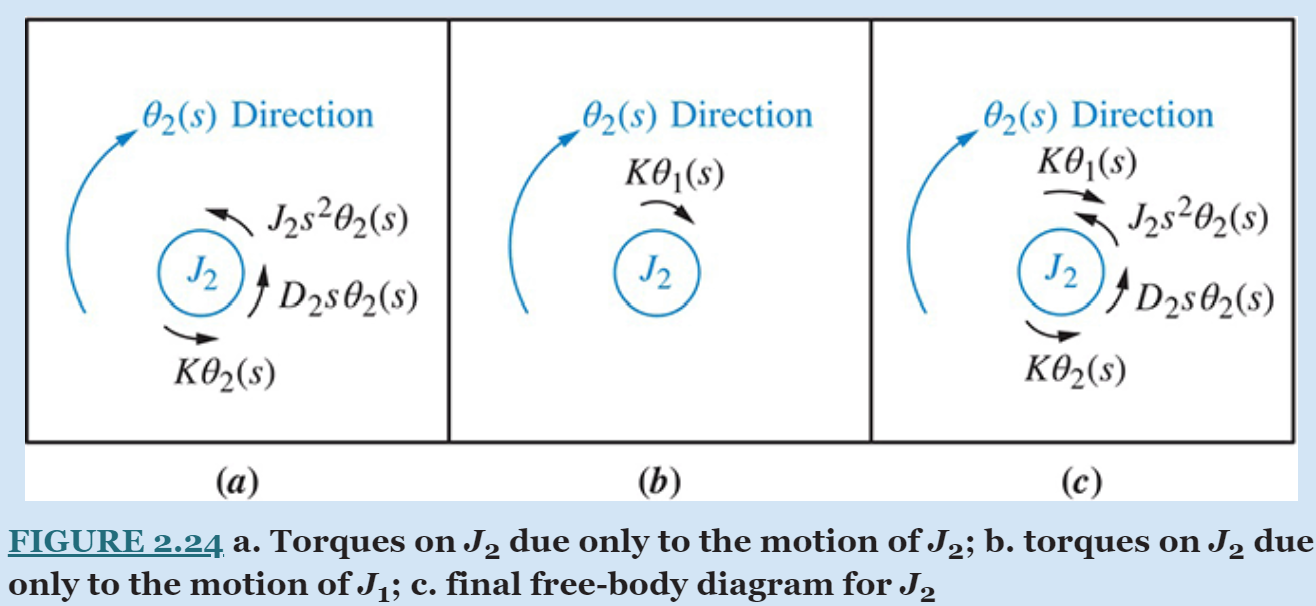

J_2*s^2*theta_2+D_2*s*theta_2+K*theta_2==K*theta_1
ans-K*theta_1
eq2 = collect(collect(ans,theta_2),theta_1)
[A,B]=equationsToMatrix([eq1, eq2],[theta_1,theta_2])
A=[J_1*s^2+ D_1*s+K     -K;
    -K               J_2*s^2+ D_2*s+K ]
collect(det(A))
B=[T;0]
A2=[A(:,1) B]
theta_2=collect(det(A2)/det(A))
G=collect(theta_2/T)

### Linearization

Consider an inverted pendulum

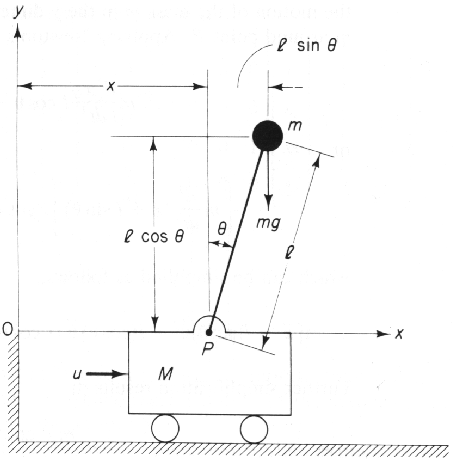

clear
syms l m M g t u(t) theta(t) x(t)
eq1 = m*l^2*(diff(theta(t), t, t)) == m*g*l*sin(theta(t))-m*l*(diff(x(t), t, t))*cos(theta(t))

$$eq1 = l^{2}\,m\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=g\,l\,m\,\sin\left(\theta \left(t\right)\right)-l\,m\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

eq2 = u(t) == M*(diff(x(t), t, t))+m*(diff(x(t)+l*sin(theta(t)), t, t))

$$eq2 = u\left(t\right)=M\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+m\,\left(\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)-l\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+l\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)$$

Now solve for the derivatives

syms x_1 x_2 x_3 x_4 x_5 x_6 v
eq3=subs(eq1,[diff(x,2),diff(theta,2)],[x_5,x_6])

$$eq3 = l^{2}\,m\,x_{6}=g\,l\,m\,\sin\left(\theta \left(t\right)\right)-l\,m\,x_{5}\,\cos\left(\theta \left(t\right)\right)$$

eq4=subs(eq2,[diff(x,2),diff(theta,2)],[x_5,x_6])

$$eq4 = u\left(t\right)=M\,x_{5}+m\,\left(-l\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+x_{5}+l\,x_{6}\,\cos\left(\theta \left(t\right)\right)\right)$$

secondDerivatives = solve([eq3, eq4], [x_5, x_6])

secondDerivatives = struct with fields:
    x_5: (l*m*sin(theta(t))*diff(theta(t), t)^2 + u(t) - g*m*cos(theta(t))*sin(theta(t)))/(- m*cos(theta(t))^2 + M + m)
    x_6: -(l*m*cos(theta(t))*sin(theta(t))*diff(theta(t), t)^2 + cos(theta(t))*u(t) - M*g*sin(theta(t)) - g*m*sin(theta(t)))/(l*(- m*cos(theta(t))^2 + M + m))


f_2=secondDerivatives.x_5

$$f\_2 = \frac{l\,m\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+u\left(t\right)-g\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)}{-m\,{\cos\left(\theta \left(t\right)\right)}^{2}+M+m}$$

f_4=secondDerivatives.x_6

$$f\_4 = -\frac{l\,m\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\cos\left(\theta \left(t\right)\right)\,u\left(t\right)-M\,g\,\sin\left(\theta \left(t\right)\right)-g\,m\,\sin\left(\theta \left(t\right)\right)}{l\,\left(-m\,{\cos\left(\theta \left(t\right)\right)}^{2}+M+m\right)}$$

f_1=x_2

$$f\_1 = x_{2}$$

f_3=x_4

$$f\_3 = x_{4}$$

f_2=subs(f_2, [x,diff(x),theta,diff(theta),u],[x_1,x_2,x_3,x_4,v])

$$f\_2 = \frac{v-g\,m\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{-m\,{\cos\left(x_{3}\right)}^{2}+M+m}$$

f_4=subs(f_4, [x,diff(x),theta,diff(theta),u],[x_1,x_2,x_3,x_4,v])

$$f\_4 = \frac{g\,m\,\sin\left(x_{3}\right)-v\,\cos\left(x_{3}\right)+M\,g\,\sin\left(x_{3}\right)}{l\,\left(-m\,{\cos\left(x_{3}\right)}^{2}+M+m\right)}$$

F=[f_1;f_2;f_3;f_4]

$$F = \left(\begin{array}{c} x_{2}\\ \frac{v-g\,m\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)}{-m\,{\cos\left(x_{3}\right)}^{2}+M+m}\\ x_{4}\\ \frac{g\,m\,\sin\left(x_{3}\right)-v\,\cos\left(x_{3}\right)+M\,g\,\sin\left(x_{3}\right)}{l\,\left(-m\,{\cos\left(x_{3}\right)}^{2}+M+m\right)} \end{array}\right)$$

at equilibrium point $\mathbf{x}_o = \mathbf{0}, u_o = 0$.

Jx=jacobian(F,[x_1 x_2 x_3 x_4])

$$Jx = \begin{array}{l} \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{g\,m\,{\cos\left(x_{3}\right)}^{2}-g\,m\,{\sin\left(x_{3}\right)}^{2}}{\sigma_{1}}-\frac{2\,m\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,\left(v-g\,m\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\right)}{{\sigma_{1}}^{2}} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{v\,\sin\left(x_{3}\right)+g\,m\,\cos\left(x_{3}\right)+M\,g\,\cos\left(x_{3}\right)}{l\,\sigma_{1}}-\frac{2\,m\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\,\left(g\,m\,\sin\left(x_{3}\right)-v\,\cos\left(x_{3}\right)+M\,g\,\sin\left(x_{3}\right)\right)}{l\,{\sigma_{1}}^{2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-m\,{\cos\left(x_{3}\right)}^{2}+M+m \end{array}$$

A=subs(Jx,[x_1 x_2 x_3 x_4 v],[0 0 0 0 0])

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{g\,m}{M} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{M\,g+g\,m}{M\,l} & 0 \end{array}\right)$$

Jv=jacobian(F,v)

$$Jv = \left(\begin{array}{c} 0\\ \frac{1}{-m\,{\cos\left(x_{3}\right)}^{2}+M+m}\\ 0\\ -\frac{\cos\left(x_{3}\right)}{l\,\left(-m\,{\cos\left(x_{3}\right)}^{2}+M+m\right)} \end{array}\right)$$

B=subs(Jv,[x_1 x_2 x_3 x_4 v],[0 0 0 0 0])

$$B = \left(\begin{array}{c} 0\\ \frac{1}{M}\\ 0\\ -\frac{1}{M\,l} \end{array}\right)$$